%% Robot 3R (planar)

clear all
close all
clc

l1 = 10;
l2 = 10;
l3 = 10;

% Cinemática inversa
Px = 27.071;
Py = 7.071;
beta = deg2rad(45)

beta = 0.7854


%Px = 7.739;
%Py = 22.885;
%beta = deg2rad(95.2)

m = Px - l3*round(cos(beta),4)

m = 20

n = Py - l3*round(sin(beta),4)

n = 0

% Theta 2
b = round(sqrt(m^2+n^2),4)

b = 20

cos_theta2 = (b^2-l2^2-l1^2)/(2*l1*l2);
sen_theta2 = sqrt(1-(cos_theta2)^2);
theta2 = atan2(sen_theta2, cos_theta2);
fprintf('theta 2 = %.4f \n',rad2deg(theta2));

theta 2 = 0.0000 


% Theta 1
alpha = atan2(n,m);
phi = atan2(l2*sen_theta2, l1+l2*cos_theta2);
theta1 = alpha - phi;
if theta1 <= -pi
    theta1 = (2*pi)+theta1;
end
fprintf('theta 1 = %.4f \n',rad2deg(theta1));

theta 1 = 0.0000 


%Theta 3
theta3 = beta - theta1 - theta2;
fprintf('theta 3 = %.4f \n',rad2deg(theta3));

theta 3 = 45.0000 


%

q1 = theta1;
q2 = theta2;
q3 = theta3;

R(1) = Link('revolute','d',0,'alpha',0,'a',l1,'offset',0);
R(2) = Link('revolute','d',0,'alpha',0,'a',l2,'offset',0);
R(3) = Link('revolute','d',0,'alpha',0,'a',l3,'offset',0);

Robot = SerialLink(R,'name','Bender')

 
Robot = 
 
Bender (3 axis, RRR, stdDH, fastRNE)                             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
|  3|         q3|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


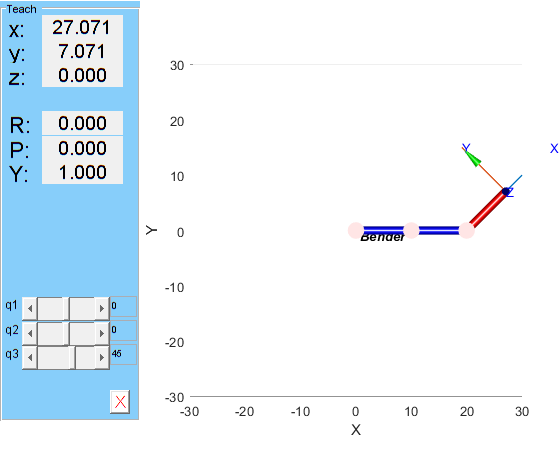


%Robot.plot([q1,q2,q3],'scale',1.0,'workspace',[-30 30 -30 30 -30 30]);
zlim([-15,30]);
Robot.teach([q1,q2,q3],'scale',1.0,'workspace',[-30 30 -30 30 -30 30],'rpy/zyx');

Robot.fkine([q1,q2,q3])

ans =     0.7071   -0.7071         0   27.0711
    0.7071    0.7071         0    7.0711
         0         0    1.0000         0
         0         0         0    1.0000
